# Deep Learning Implementation with Yolov2 for Object Detection

In this live script, we explore the application of machine learning for image classification. The focus is on using a camera to capture images of different objects, such as oranges and apples, and applying deep learning techniques to accurately classify these images. This example demonstrates how classification models can be trained and utilized to enhance tasks such as pick-and-place operations in industrial robots. By integrating image classification with robotic systems, we illustrate a possible practical application of machine learning in automating and optimizing industrial processes. A real-time implementation is illustrated in the following [**video**](https://www.youtube.com/watch?v=CyfoL8sGzS4)**.** 

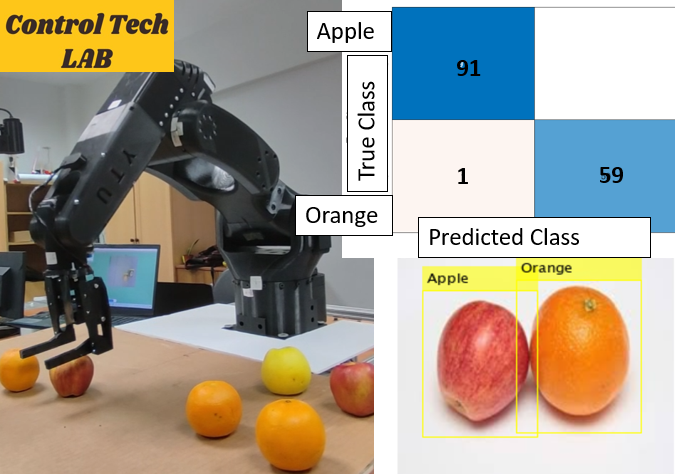

## 1. Introduction to Neural Networks

Neural Networks are a fascinating concept inspired by the understanding of the human brain's workings. They form the backbone of what we today refer to as Deep Learning. Let's explore this concept further.

### The Concept of Neural Networks

A neural network is a series of algorithms that seek to recognize underlying relationships in a set of data through a process that mimics the way the human brain operates. In this sense, neural networks refer to systems of neurons, either organic or artificial.

### The Human Brain vs. Artificial Neural Networks

The human brain is composed of neurons that process and transmit information through electrical and chemical signals. These neurons are connected by synapses, which are responsible for memory and learning. Artificial Neural Networks (ANNs), in a similar manner, consist of interconnected units (or nodes) that process information by responding to external inputs, relaying information between each unit. The process requires multiple passes at the data to find connections and derive meaning from undefined data.

## 2. CNN Convolutional Neural Network

A Convolutional Neural Network (CNN) is a specialized type of deep learning model primarily developed for processing data with a grid-like topology, such as images and videos. It is composed of a series of computational nodes, known as neurons, which are organized into various layers. Each neuron in a layer is connected to a set of neurons in the previous and subsequent layers, facilitating a hierarchical analysis of the input data.

CNNs can greatly vary in architecture and depth. For instance, AlexNet, a well-known CNN architecture, contains eight layers, while GoogLeNet (also known as Inception v1) includes 22 layers, contrary to the misstated numbers. Despite these differences, there are several standard layers common to all CNNs, such as the input layer designed to receive the image data, and convolutional layers responsible for feature extraction.

### Difference Between CNN and Classical Neural Network:

In a traditional neural network, also known as a fully connected network or MultiLayer perceptron (MLP), each neuron receives inputs from every neuron in the previous layer, processes the input through a weighted sum followed by a non-linear activation function, and produces a single output value. This output then serves as part of the input for the subsequent layer's neurons. 

This design does not take into account the spatial hierarchy of the input data.

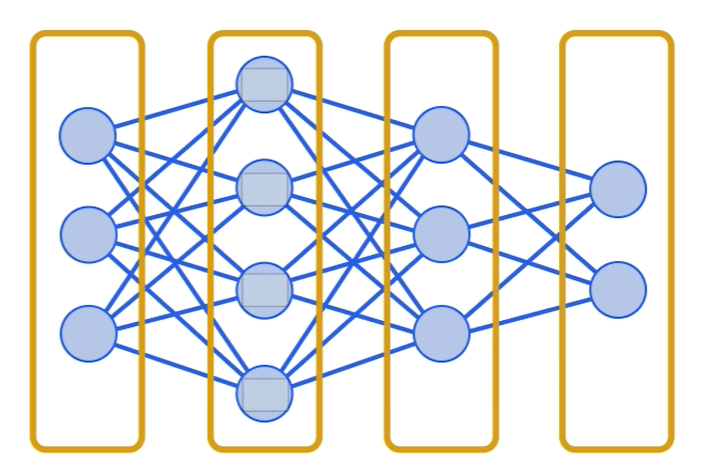

Conversely, CNNs maintain the spatial structure of the input data. This is critical when processing images since the relationship between adjacent pixels carries significant information about the structure within the image. Rather than flattening the image into a one-dimensional vector, as in classical neural networks, CNNs process the image in its two-dimensional form. Each neuron in a convolutional layer focuses on a small region of the input image - this field of view is known as the local receptive field - and the output is a two-dimensional activation map that conveys the presence of specific features in the input.

CNNs maintain the spatial structure of the input data 

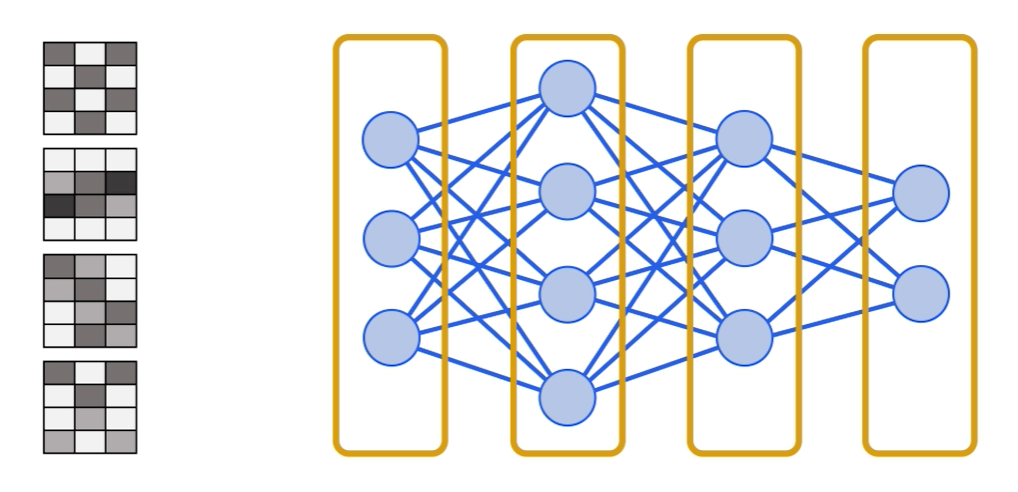

### Then, how CNNs process images?

A CNN deconstructs the input image into a collection of features by using filters, also called kernels. Each filter in a convolutional layer is designed to extract a specific type of feature, such as edges, textures, or color gradients. The feature maps produced by these filters retain the spatial dimensions of the original image, which allows the network to understand the hierarchical structure.

The 'learned' aspect of these filters is fundamental: during training, the network uses backpropagation to adjust the filter values, or weights, to minimize the difference between the predicted and actual outcomes. Through this learning process, the network determines which features are most useful for classifying images or performing other image-related tasks.

### So what network to use?

#### In the process of choosing a network for a machine learning task, there are three main options:

- Pretrained Network

- Using transfer learning on a pretrained network

- Make a costume network for your project

#### Pre-trained Network:

A pre-trained network is often a suitable choice as there are many networks that have been trained on millions of images. These networks are well-tuned for general tasks, including notable examples such as AlexNet, GoogLeNet, ResNet-50, and more. However, sometimes a specific task requires capabilities that generic pre-trained networks do not offer. In such cases, we might opt for transfer learning with a pre-trained network or design a custom network.

#### Transfer Learning:

Transfer learning is a method where we take an already trained network and fine-tune it using our own dataset. This approach is advantageous because it saves time, requires less labelled data, and can reduce the likelihood of overfitting, particularly when the new dataset is smaller. This technique often involves modifying the final layers of the network to better suit the new task, and selectively retraining certain layers of the network while keeping others frozen.

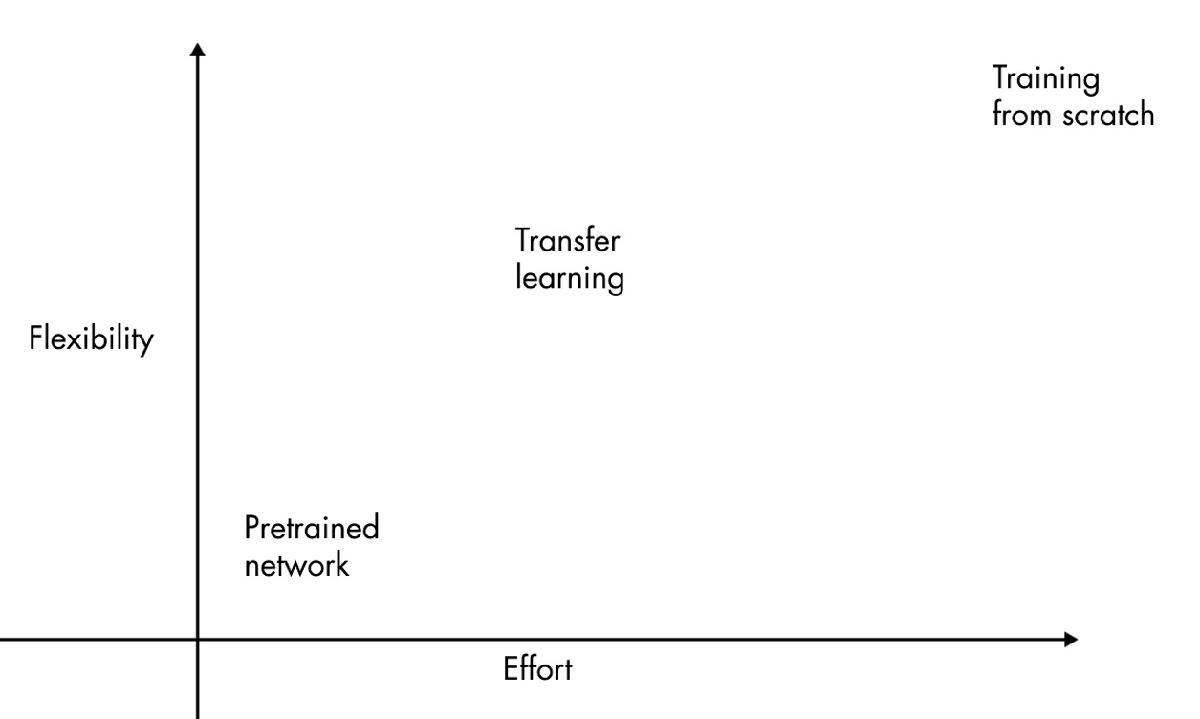

#### Custom Network:

When might we need a custom network? One reason is if our data significantly differ in size or distribution from the data used in common pretrained models, which often assume image inputs of size around 224x224x3.However, designing and training a custom network is a complex task. It requires a detailed understanding of various architectural choices and hyperparameters. A simple custom network architecture might include a sequence of layers such as convolutional layers, activation functions (e.g., ReLU), pooling layers, and fully connected layers, culminating in a softmax layer for classification.

Here is an example of a basic Convolutional Neural Network (CNN) architecture:

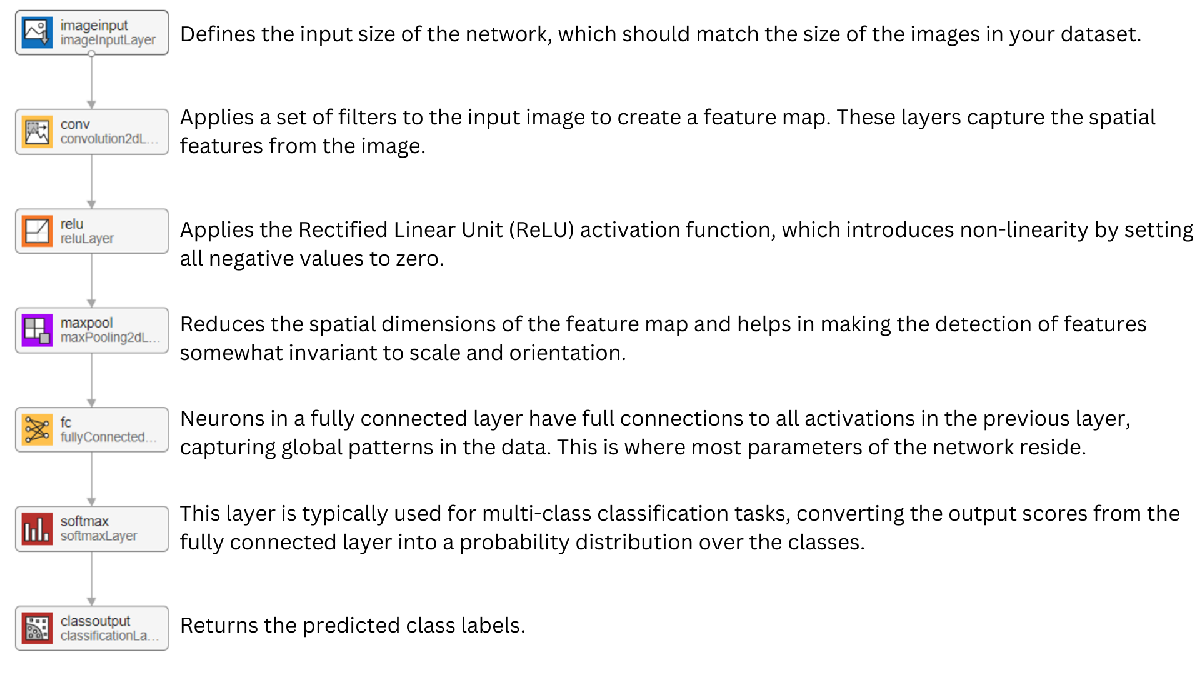

## 3. Transfer Learning

#### Transfer learning is the most appropriate method for this task. To begin with transfer learning, we need:

- **Pretrained CNN:** We have chosen ResNet-18, a relatively lightweight model compared to its deeper counterparts like ResNet-50 or ResNet-101, which strikes a balance between performance and computational efficiency.

- **Dataset for the New Task:** Our dataset comprises images of oranges and apples. The dataset's quality and the way it has been labeled are crucial for the success of transfer learning.

- **Algorithm Options:** We have several options for optimization algorithms, including Adam, SGD (Stochastic Gradient Descent), RProp, and LBFGS. Each optimizer has unique characteristics.

There are some important aspects of the algorithms options that can be changed according to the task that we have some of the most important hyperparameters are:

- `InitialLearnRate`**:** This is the initial rate at which the network learns. In many algorithms, it decays over time as the learning progresses.

- `Epochs`**:** This is one full training cycle on the entire dataset. Multiple epochs are often required for the model to converge to an optimal solution.

- `MiniBatchSize`**: **This specifies the subset size of your training dataset that the model will see before it updates the internal model parameters. The number of iterations per epoch is equal to the ceiling of the number of data points divided by the `MiniBatchSize``.`

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:01:01 |       48.44% |       1.1338 |      1.0000e-04 |
|      13 |          50 |       00:20:10 |      100.00% |       0.0002 |      1.0000e-04 |
|      20 |          80 |       00:31:17 |      100.00% |   5.2835e-05 |      1.0000e-04 |
|========================================================================================|
Training finished: Max epochs completed.


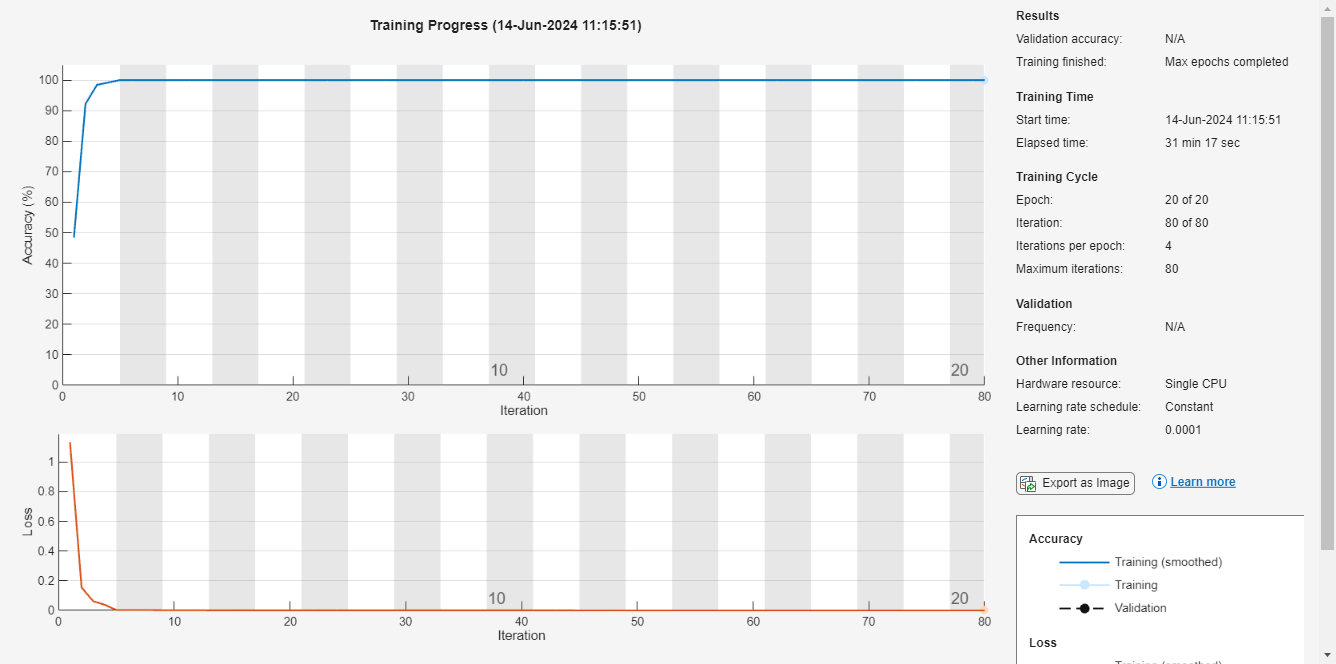

% Set up the base directory for the dataset. You need to provide the path to the directory where your dataset is located.
dataDir_class_1 = fullfile("C:\Users\Claudia Yasar\Documents\Intelligent Control Systems\Inteligent control system_after_comments\Week_6\Object_Detection\Object_Detection");%% add your path directory

% Append the 'fruit' subdirectory to the base directory. This subdirectory should contain the fruit images.
dataDir_class = dataDir_class_1 + "\fruit"; 

% Load the pretrained network from a file called 'transfered_net.mat'.
load transfered_net 

% Create an imageDatastore for managing the image data. This datastore will automatically label the images based on the folder names and include all subdirectories.
imds = imageDatastore(dataDir_class, "IncludeSubfolders", true, "LabelSource", "foldernames"); 

% Split the image data into a training set and a test set. Here, 80% of the images will be used for training, and 20% for testing.
[trainImgs, testImgs] = splitEachLabel(imds, 0.80); 

% Prepare the training image data for the network by resizing all images to 224x224 pixels, which is the default input size for ResNet architectures.
trainds = augmentedImageDatastore([224 224], trainImgs); 

% Similarly, prepare the test image data by resizing the images to 224x224 pixels.
testds = augmentedImageDatastore([224 224], testImgs); 

% Define the training options for the neural network. 'rmsprop' is the optimization algorithm, the initial learning rate is set to 0.0001, a plot will show the training progress, and the training will run for a maximum of 20 epochs.
options = trainingOptions("rmsprop", "InitialLearnRate", 0.0001, "Plots", "training-progress", "MaxEpochs", 20); 

% Train the neural network using the specified training data, preloaded network, and the defined training options.
net = trainNetwork(trainds, transfered_net, options);

## Classification

Image classification is a fundamental task in computer vision and deep learning. It involves predicting a category or label for a given input image. The model we've trained is designed to differentiate between apples and oranges. Once the model is trained, we can evaluate its performance on a separate test set of images. This evaluation is critical to understand how well the model generalizes to unseen data. The accuracy of the model on the test set gives us a quantifiable measure of its performance.

% Using the trained network 'net' to classify the images in the test dataset 'testds'.
testPreds = classify(net, testds); 

% Calculating the accuracy of the predictions by comparing them with the actual labels, 
% then dividing the number of correct predictions (nnz(...) - number of non-zero elements, 
% here used to count the number of true conditions) by the total number of predictions made.
acc = nnz(testPreds == testImgs.Labels) / length(testPreds) 

acc = 0.9934

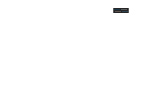


% Generating a confusion matrix to visualize the performance of the classification model.
% This chart shows how many images were correctly classified and how many were misclassified, and into which categories the errors were made.
confusionchart(testImgs.Labels, testPreds); 

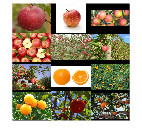


% Below is the code for trying out the classification model on a different set of images. 
% This part is separate from the above testing and is for additional verification of the model's generalization capability.

% Specify the directory of the new image set that you want to classify.
dataDir_class_test_1 = fullfile("C:\Users\Claudia Yasar\Documents\Intelligent Control Systems\Inteligent control system_after_comments\Week_6\Object_Detection\Object_Detection"); % Add the path to your test images directory here

% Append the 'outsourcetest' subdirectory to the base directory. This directory should contain the images to be classified.
dataDir_class_test = dataDir_class_test_1 + "\outsourcetest"; 

% Create an imageDatastore for the new image set without automatic labelling, 
% as we only want to classify these images, not train on them.
imds_outtest = imageDatastore(dataDir_class_test); 

% Display the images in a montage to have a visual check of the images to be classified.
montage(imds_outtest) 


% Prepare the new image set for classification by resizing all images to 224x224 pixels, the expected input size for the network.
auds = augmentedImageDatastore([224 224], imds_outtest); 

% Classify the new image set using the pretrained network and get the predicted labels along with the associated probabilities.
[predictedLabels, probs] = classify(net, auds)

predictedLabels = 12×1 categorical array
     Apple 
     Apple 
     Apple 
     Apple 
     Apple 
     Apple 
     Apple 
     Orange 
     Orange 
     Orange 
     Apple 
     Orange 


probs = 12×2 single matrix
    1.0000    0.0000
    1.0000    0.0000
    0.9999    0.0001
    0.9991    0.0009
    0.7551    0.2449
    0.9955    0.0045
    0.9989    0.0011
    0.0000    1.0000
    0.0122    0.9878
    0.0000    1.0000


## 4. Object Detection

Object detection is a complex task within the field of computer vision that involves identifying and localizing multiple objects within an image or video. Unlike image classification, which assigns a single label to an entire image, object detection recognizes multiple objects, each with a corresponding bounding box and classification label.

Approaches to Object Detection:

- **Region-based approaches: **These include methods like R-CNN (Region-based Convolutional Neural Networks) and its variations like Fast R-CNN and Faster R-CNN. These approaches first propose candidate object regions and then classify each region using a CNN.

- **Single-shot approaches:** Single-shot detectors (SSDs) like YOLO (You Only Look Once) perform object detection in a single forward pass of the network, predicting both class and location simultaneously. These are typically faster than region-based approaches and are more suitable for real-time processing.

- **Anchor-based approaches:** Many detectors, including Faster R-CNN and YOLO, use anchor boxes as reference points. These are predefined boxes of various shapes and sizes that the network uses to predict the actual bounding boxes of objects.

**YOLO (You Only Look Once):**

YOLO is a popular single-shot, anchor-based approach that is known for its speed and efficiency. Here’s how YOLO works:

- **Grid Division:** The input image is divided into an $S 
x S$ grid, and each grid cell is responsible for detecting objects whose center falls within it.

- **Bounding Box Prediction:** For each grid cell, YOLO predicts multiple bounding boxes and confidence scores for those boxes. The confidence scores reflect the likelihood of an object being present and how accurate the box is.

- **Class Probabilities:** Alongside bounding box predictions, the network also outputs class probabilities for each grid cell.

- **Non-Max Suppression:** To refine the predictions, YOLO uses a technique called non-maximum suppression (NMS) to filter out overlapping boxes based on their confidence scores, keeping only the best box for each object.

- **Anchor Boxes: **YOLO employs anchor boxes at each grid cell to predict bounding boxes. The network learns to adjust these anchor boxes to match the true bounding boxes during training.

- **Intersection over Union (IoU): **YOLO uses IoU to measure the overlap between predicted bounding boxes and ground truth boxes. It helps during training to improve the accuracy of bounding box predictions.

% Load labeled data from a .mat file containing training data
data = load('apple_orange_gTruth_nopath.mat');
trainingData = data.apple_orange_gTruth_nopath;

% Specify the directory where the training sample images are stored.
% This should be the full path to your images directory.
% Example path format (uncomment the next line and replace with your path):
% dataDir = 'C:\Users\YourName\Path\To\Your\Images';
dataDir = fullfile("C:\Users\Claudia Yasar\Documents\Intelligent Control Systems\Inteligent control system_after_comments\Week_6\Object_Detection\Object_Detection");

% Update the imageFilename column in the training data table with the full file paths
trainingData.imageFilename = fullfile(dataDir, trainingData.imageFilename);

% Create an imageDatastore containing the file paths of the labeled images
imds = imageDatastore(trainingData.imageFilename);

% Seed the random number generator for reproducibility
rng(0);

% Shuffle the indices of the training data randomly
shuffledIndices = randperm(height(trainingData));

% Calculate the index for a 60% split of the training data
idx = floor(0.6 * length(shuffledIndices));

% Split the data into 60% training, 10% validation, and 30% testing
trainingIdx = 1:idx;
trainingDataTbl = trainingData(shuffledIndices(trainingIdx),:);
validationIdx = idx+1 : idx + 1 + floor(0.1 * length(shuffledIndices));
validationDataTbl = trainingData(shuffledIndices(validationIdx),:);
testIdx = validationIdx(end)+1 : length(shuffledIndices);
testDataTbl = trainingData(shuffledIndices(testIdx),:);

% Prepare the datastores for training, validation, and test datasets
imdsTrain = imageDatastore(trainingDataTbl{:,'imageFilename'});
bldsTrain = boxLabelDatastore(trainingDataTbl(:,2:end));
imdsValidation = imageDatastore(validationDataTbl{:,'imageFilename'});
bldsValidation = boxLabelDatastore(validationDataTbl(:,2:end));
imdsTest = imageDatastore(testDataTbl{:,'imageFilename'});
bldsTest = boxLabelDatastore(testDataTbl(:,2:end));

% Combine the image and box label datastores for each dataset
trainingData1 = combine(imdsTrain,bldsTrain);
validationData1 = combine(imdsValidation,bldsValidation);
testData1 = combine(imdsTest,bldsTest);

% Transform the datasets by rescaling the images and labels to match the input layer size
scaledTrainData = transform(trainingData1,@scaleGT);
scaledValData = transform(validationData1,@scaleGT);
scaledTestData = transform(testData1,@scaleGT);

% Estimate anchor boxes for the training dataset
[anchorBoxes, meanIoU] = estimateAnchorBoxes(scaledTrainData, 7);

% Define the number of classes and image size for the object detection
numClasses = 2;
imageSize = [224 224 3];

% Define the YOLOv2 network layers using the predefined anchor boxes
lgraph = yolov2Layers(imageSize,numClasses,anchorBoxes,net,"res5b_relu","ReorgLayerSource","res3a_relu");

% Set training options including the use of RMSprop optimizer, minibatch size,
% learning rate, maximum number of epochs, checkpoint path for saving models,
% validation data, and plotting of training progress

options = trainingOptions('rmsprop', ...
        'MiniBatchSize',16, ....        % Set the size of mini-batch for gradient estimation to 16 samples
        'InitialLearnRate',0.0001,....  % Set the starting learning rate for the training to 0.0001
        'MaxEpochs',50, ...            % Set the maximum number of epochs for training to 30
        'CheckpointPath',tempdir, ...  % Save checkpoints of the network weights to the temporary directory during training
        'ValidationData',scaledValData,....% Specify the validation data to be used during training
        'Plots','training-progress',.... % Display a plot of training progress, which includes loss and accuracy
        'ValidationFrequency',10); % Check the validation metrics every 10 iterations of the algorithm
% Train the YOLOv2 object detector using the specified layers and options
[detector, info] = trainYOLOv2ObjectDetector(scaledTrainData, lgraph, options);

*************************************************************************
Training a YOLO v2 Object Detector for the following object classes:

* Apple
* Orange

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:14 |         3.13 |         3.14 |       9.7847 |       9.8557 |      1.0000e-04 |
|       1 |          10 |       00:01:03 |         2.32 |         2.36 |       5.3693 |       5.5832 |      1.0000e-04 |
|       1 |          20 |       00:01:54 |       

%%%%%%%%%%%%%trying the model%%%%%%%%%%%%%%%%%%%% 
 
 I = imread('apple_orange2.jpg'); % Read the image 'apple_orange1.jpg' into MATLAB
 I = imresize(I,[224 224]); % Resize the image to be 224x224 pixels, which is the input size expected by the network
 [bboxes,scores,name] = detect(detector,I); % Detect objects in the resized image using the trained detector and output the bounding boxes, scores, and class names
I = insertObjectAnnotation(I,'rectangle',bboxes,name); % Annotate the detected objects on the image with rectangles and their class names
figure % Create a new figure
imshow(I) % Show the annotated image

detectionResults1 = detect(detector, imds); %% Test the model using the image data store

%% Calculate the Detection Precision using the average precision, recall, and precision metrics for the detected results
[averagePrecision,recall,precision] = evaluateDetectionPrecision(detectionResults1, trainingData(:,2:end))

bar(averagePrecision) % Create a bar graph of the average precision values
xticklabels(trainingData.Properties.VariableNames(2:end)) % Set the x-axis tick labels to the variable names of the training data (excluding the first column)
xtickangle(45) % Angle the x-axis tick labels at 45 degrees
title("Precision") % Title of the bar graph

figure % Create a new figure
hold on % Hold the current graph, allowing multiple plots to be drawn on the same figure
for k = 1:numel(recall) % Loop over each class's recall vector
plot(recall{k}, precision{k}) % Plot the precision-recall curve for each class
end
hold off % Release the hold so that new plots do not draw over this figure
xlabel("Recall") % X-axis label
ylabel("Precision") % Y-axis label
title("Precision-Recall Curve") % Title of the precision-recall curve plot
legend(trainingData.Properties.VariableNames(2:end)) % Create a legend using the variable names of the training data (excluding the first column)

[am, fppi, missRate] = evaluateDetectionMissRate(detectionResults1, trainingData(:,2:end));
bar(am) % Create a bar graph of the log-average miss rate
xticklabels(trainingData.Properties.VariableNames(2:end)) % Set the x-axis tick labels to the variable names of the training data (excluding the first column)
xtickangle(45) % Angle the x-axis tick labels at 45 degrees
title("Log-Average Miss Rate") % Title of the log-average miss rate graph

% Save the trained detector to a .mat file
save('trainedYOLOv2Detector.mat', 'detector');

## 5. Try Your Model with a Webcam

load('trainedYOLOv2Detector.mat');
camera =webcam(2);    
    while true
        % Acquire an image frame from the webcam
        img = snapshot(camera);
    
        % Detect objects in the image
        % The detect function's actual call might be different based on your detector
        [bboxes, scores, labels] = detect(detector, img);
    
        % Annotate the image with the detections
        imgAnnotated = insertObjectAnnotation(img, 'rectangle', bboxes, labels);
    
        % Display the image
        imshow(imgAnnotated);
        title('Detected Objects');
        
        % Exit the loop if the 'q' key is pressed
        drawnow;
        pause(0.01); % Pause to allow for a key press check
        if get(gcf,'CurrentCharacter') == 'q'
            break;
        end
    end

% Clean up
clear('camera');


function data = scaleGT(data)  
    targetSize = [224 224];
    % data{1} is the image
    scale = targetSize./size(data{1},[1 2]);
    data{1} = imresize(data{1},targetSize);
    % data{2} is the bounding box
    data{2} = bboxresize(data{2},scale);
end


It is a work by